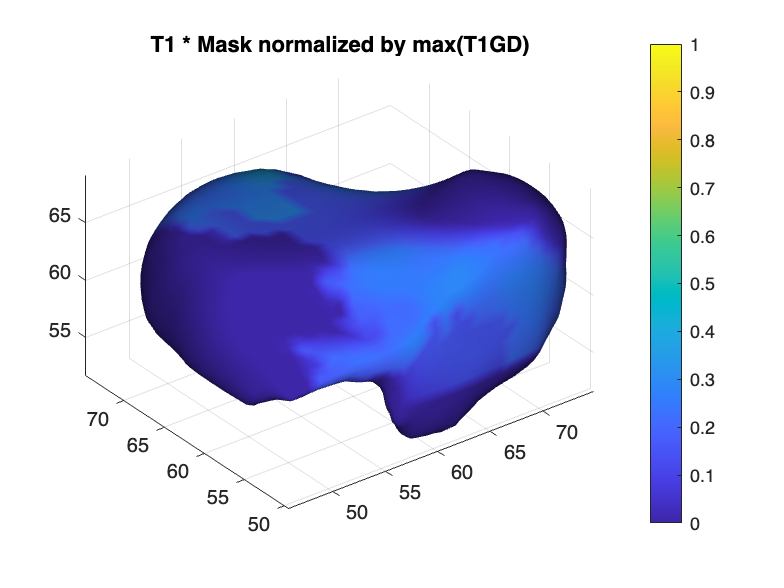

% T1 * Mask normalized by T1GD
% Load data
nii_t1 = double(niftiread('RJ_009_A0/RJ_009_A0_T1.nii.gz'));
nii_t1gd = double(niftiread('RJ_009_A0/RJ_009_A0_T1Gd.nii.gz'));
nii_mask = niftiread('RJ_009_A0/RJ_009_A0_label(1).nii.gz');

% T1 * mask
masked_img = nii_t1 .* double(nii_mask);

% lumen: dark region
lumen_threshold = 0.3 * max(masked_img(:));  % ~30% of max
lumen_mask = masked_img < lumen_threshold;

% Wall mask = label - lumen
wall_mask = nii_mask & ~lumen_mask;

% Create surface from wall mask
fv = isosurface(wall_mask, 0.5);
fv = smoothpatch(fv, 1, 10);  % smoothing

% Normalize masked T1 by max T1gd
max_t1gd = max(nii_t1gd(nii_mask > 0));
nii_t1_norm = masked_img / max_t1gd;

% Interpolator for normalized T1
[x, y, z] = ndgrid(1:size(nii_t1_norm,1), 1:size(nii_t1_norm,2), 1:size(nii_t1_norm,3));
interpFunc = griddedInterpolant(x, y, z, nii_t1_norm, 'linear', 'nearest');

% Compute normals
normals = isonormals(double(wall_mask), fv.vertices);

% Sample SI along normals
max_sis = zeros(size(fv.vertices, 1), 1);
step = 0.1;
for i = 1:size(fv.vertices, 1)
    vertex = fv.vertices(i,:);
    normal = normals(i,:) / (norm(normals(i,:)) + eps);

    sis = [];
    for t = 0:step:1.2
        sample_point = vertex + t * normal;
        sis(end+1) = interpFunc(sample_point(1), sample_point(2), sample_point(3));
    end
    max_sis(i) = max(sis);
end

% Visualize
figure;
trisurf(fv.faces, fv.vertices(:,1), fv.vertices(:,2), fv.vertices(:,3), ...
    max_sis, ...
    'FaceColor', 'interp', 'EdgeColor', 'none');
colormap parula;
colorbar;
clim([0 1]); 
axis equal;
view(3);
lighting gouraud;
camlight headlight;
material dull;
title('T1 * Mask normalized by max(T1GD)');

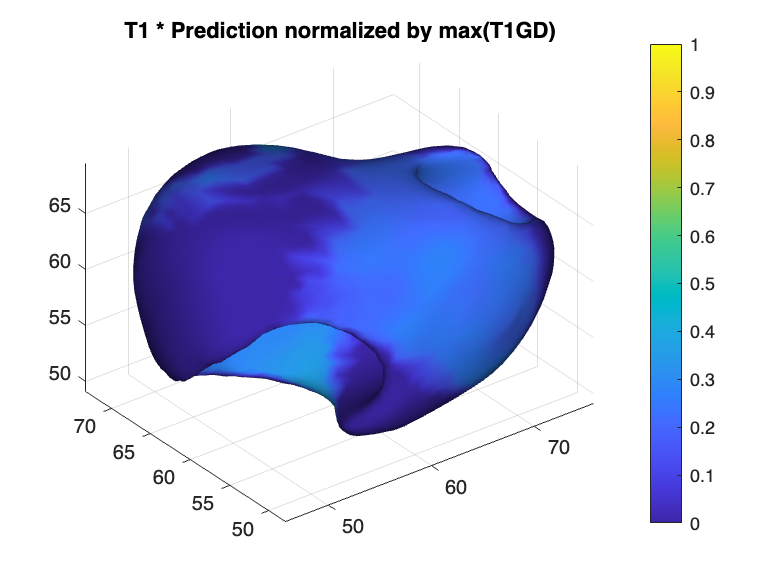

% T1 * Prediction normalized by T1GD
% Load data
nii_t1 = double(niftiread('RJ_009_A0/RJ_009_A0_T1.nii.gz'));
nii_t1gd = double(niftiread('RJ_009_A0/RJ_009_A0_T1Gd.nii.gz'));
nii_mask = niftiread('RJ_009_A0/RJ_009_A0_pred.nii.gz');
% T1 * mask
masked_img = nii_t1 .* double(nii_mask);

% lumen: dark region
lumen_threshold = 0.3 * max(masked_img(:));  % ~30% of max
lumen_mask = masked_img < lumen_threshold;

% Wall mask = label - lumen
wall_mask = nii_mask & ~lumen_mask;

% Create surface from wall mask
fv = isosurface(wall_mask, 0.5);
fv = smoothpatch(fv, 1, 10);  % smoothing

% Normalize masked T1 by max T1gd
max_t1gd = max(nii_t1gd(nii_mask > 0));
nii_t1_norm = masked_img / max_t1gd;

% Interpolator for normalized T1
[x, y, z] = ndgrid(1:size(nii_t1_norm,1), 1:size(nii_t1_norm,2), 1:size(nii_t1_norm,3));
interpFunc = griddedInterpolant(x, y, z, nii_t1_norm, 'linear', 'nearest');

% Compute normals
normals = isonormals(double(wall_mask), fv.vertices);

% Sample SI along normals
max_sis = zeros(size(fv.vertices, 1), 1);
step = 0.1;
for i = 1:size(fv.vertices, 1)
    vertex = fv.vertices(i,:);
    normal = normals(i,:) / (norm(normals(i,:)) + eps);

    sis = [];
    for t = 0:step:1.2
        sample_point = vertex + t * normal;
        sis(end+1) = interpFunc(sample_point(1), sample_point(2), sample_point(3));
    end
    max_sis(i) = max(sis);
end

% Visualize
figure;
trisurf(fv.faces, fv.vertices(:,1), fv.vertices(:,2), fv.vertices(:,3), ...
    max_sis, ...
    'FaceColor', 'interp', 'EdgeColor', 'none');
colormap parula;
colorbar;
clim([0 1]); 
axis equal;
view(3);
lighting gouraud;
camlight headlight;
material dull;
title('T1 * Prediction normalized by max(T1GD)');

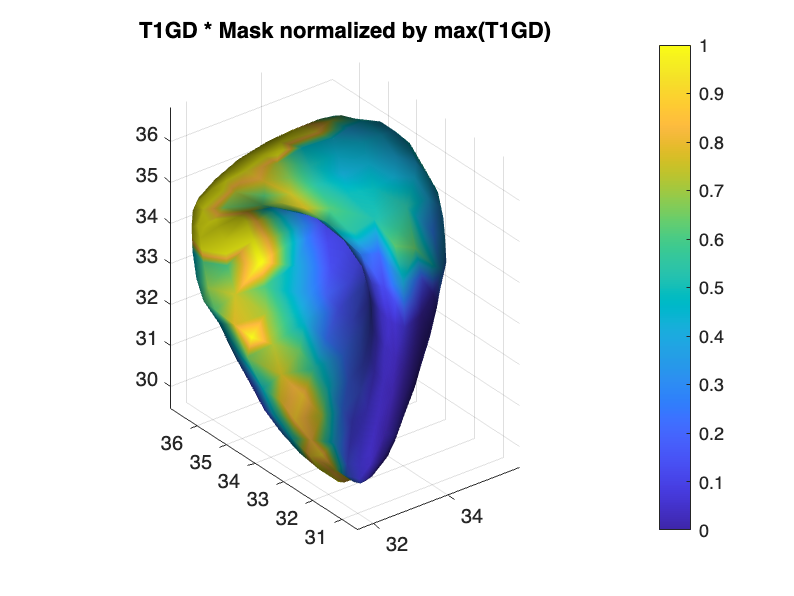

% T1GD * Mask normalized by T1GD
% Load Data
nii_t1gd = double(niftiread('data/T1Gd_014_0000.nii.gz'));
nii_t1 = double(niftiread('data/T1_014_0000.nii.gz'));
nii_mask = niftiread('data/T1_014_label.nii.gz'); 

% Step 1: Apply mask to T1GD
masked_img = nii_t1gd .* double(nii_mask);

% Step 2: Extract lumen from T1 using threshold
masked_t1 = nii_t1 .* double(nii_mask);
lumen_threshold = 0.3 * max(masked_t1(:));  % ~30% of max
lumen_mask = masked_t1 < lumen_threshold;

% Step 3: Define wall mask as (mask minus lumen)
wall_mask = nii_mask & ~lumen_mask;

% Step 4: Generate surface from wall mask
fv = isosurface(wall_mask, 0.5);
fv = smoothpatch(fv, 1, 10);  % Optional smoothing

% Step 5: Normalize masked T1gd by its max inside mask
max_t1gd = max(nii_t1gd(nii_mask > 0));
nii_t1gd_norm = masked_img / max_t1gd;

% Step 6: Interpolator
[x, y, z] = ndgrid(1:size(nii_t1gd_norm,1), 1:size(nii_t1gd_norm,2), 1:size(nii_t1gd_norm,3));
interpFunc = griddedInterpolant(x, y, z, nii_t1gd_norm, 'linear', 'nearest');

% Step 7: Compute normals
normals = isonormals(double(wall_mask), fv.vertices);

% Step 8: Sample intensity along normals
max_sis = zeros(size(fv.vertices, 1), 1);
step = 0.1;
for i = 1:size(fv.vertices, 1)
    vertex = fv.vertices(i,:);
    normal = normals(i,:) / (norm(normals(i,:)) + eps);
    
    sis = [];
    for t = 0:step:1.2
        sample_point = vertex + t * normal;
        sis(end+1) = interpFunc(sample_point(1), sample_point(2), sample_point(3));
    end
    max_sis(i) = max(sis);
end

% Step 9: Visualize
figure;
trisurf(fv.faces, fv.vertices(:,1), fv.vertices(:,2), fv.vertices(:,3), ...
    max_sis, ...
    'FaceColor', 'interp', 'EdgeColor', 'none');
colormap parula; 
colorbar;
clim([0 1]); 
axis equal;
view(3);
lighting gouraud;
camlight headlight;
material dull;
title('T1GD * Mask normalized by max(T1GD)');

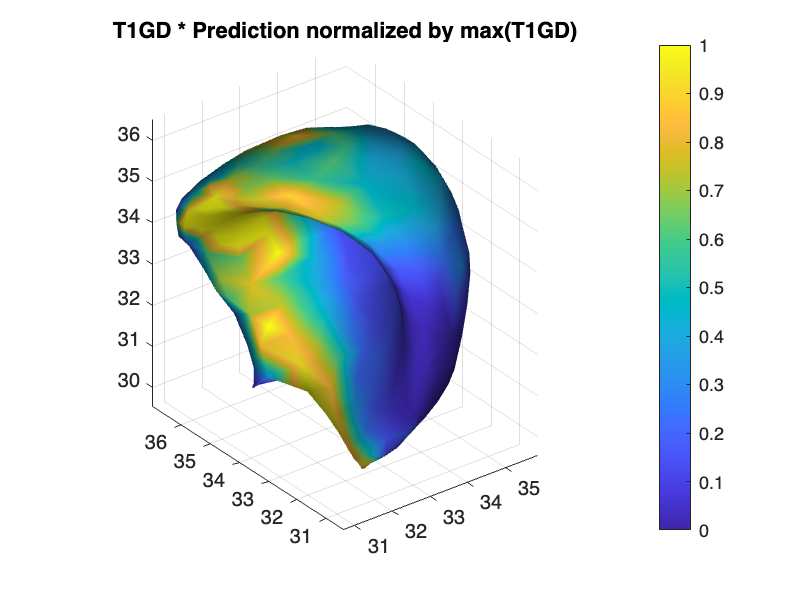

% T1GD * Prediction normalized by T1GD
% Load Data
nii_t1gd = double(niftiread('data/T1Gd_014_0000.nii.gz'));
nii_t1 = double(niftiread('data/T1_014_0000.nii.gz'));
nii_mask = niftiread('data/T1_014_prediction.nii.gz'); 

% Step 1: Apply mask to T1GD
masked_img = nii_t1gd .* double(nii_mask);

% Step 2: Extract lumen from T1 using threshold
masked_t1 = nii_t1 .* double(nii_mask);
lumen_threshold = 0.3 * max(masked_t1(:));  % ~30% of max
lumen_mask = masked_t1 < lumen_threshold;

% Step 3: Define wall mask as (mask minus lumen)
wall_mask = nii_mask & ~lumen_mask;

% Step 4: Generate surface from wall mask
fv = isosurface(wall_mask, 0.5);
fv = smoothpatch(fv, 1, 10);  % Optional smoothing

% Step 5: Normalize masked T1gd by its max inside mask
max_t1gd = max(nii_t1gd(nii_mask > 0));
nii_t1gd_norm = masked_img / max_t1gd;

% Step 6: Interpolator
[x, y, z] = ndgrid(1:size(nii_t1gd_norm,1), 1:size(nii_t1gd_norm,2), 1:size(nii_t1gd_norm,3));
interpFunc = griddedInterpolant(x, y, z, nii_t1gd_norm, 'linear', 'nearest');

% Step 7: Compute normals
normals = isonormals(double(wall_mask), fv.vertices);

% Step 8: Sample intensity along normals
max_sis = zeros(size(fv.vertices, 1), 1);
step = 0.1;
for i = 1:size(fv.vertices, 1)
    vertex = fv.vertices(i,:);
    normal = normals(i,:) / (norm(normals(i,:)) + eps);
    
    sis = [];
    for t = 0:step:1.2
        sample_point = vertex + t * normal;
        sis(end+1) = interpFunc(sample_point(1), sample_point(2), sample_point(3));
    end
    max_sis(i) = max(sis);
end

% Step 9: Visualize
figure;
trisurf(fv.faces, fv.vertices(:,1), fv.vertices(:,2), fv.vertices(:,3), ...
    max_sis, ...
    'FaceColor', 'interp', 'EdgeColor', 'none');
colormap parula;  % or use colormap_blueyellow()
colorbar;
clim([0 1]);  % since normalized by max
axis equal;
view(3);
lighting gouraud;
camlight headlight;
material dull;
title('T1GD * Prediction normalized by max(T1GD)');